# **General Guide**

### **Fitting the MATLAB Logo Using Neural Networks**

This live script demonstrates the workflow of using a neural network for regression. The first five sections provide 

detailed usage instructions, while **the sixth section offers quick commands that allow users to solve fitting **

**problems with just a few lines of code. (Read the first section to make sure the format of the data are **

**correct.)**

### 1. **Format Requirement**

To represent neural network computations using linear algebra notation, 

both the input data and corresponding labels should be column vectors.

For example: $f\left(x_1 ,x_2 \right):R^2 \to R^2 =\left(x_1^2 +x_2^2 ,{2x}_1^2 +x_2^2 \right)$

                                                                 
$$\begin{array}{l}
{\mathit{\mathbf{d}}}_1 =\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack \;,{\mathit{\mathbf{d}}}_2 \;=\left\lbrack \begin{array}{c}
1\\
2
\end{array}\right\rbrack ,\;\cdots \;,{\mathit{\mathbf{d}}}_N =\left\lbrack \begin{array}{c}
x_{1N} \\
x_{2N} 
\end{array}\right\rbrack \\
{\mathit{\mathbf{y}}}_1 =\left\lbrack \begin{array}{c}
1\\
3
\end{array}\right\rbrack \;,{\;\mathit{\mathbf{y}}}_2 \;=\;\left\lbrack \begin{array}{c}
5\\
6
\end{array}\right\rbrack ,\;\cdots \;,{\mathit{\mathbf{y}}}_N \;=\left\lbrack \begin{array}{c}
x_{1N}^2 +x_{2N}^2 \\
{2x}_{1N}^2 +x_{2N}^2 
\end{array}\right\rbrack 
\end{array}$$


    data : $\mathit{\mathbf{D}}\in R^{n_D \times N}$ ($n_D \times N$ Matrix), where $n_D$ is the dimension of data and $N$ is the number of data points. 

    label : $\mathit{\mathbf{Y}}\in R^{n_L \times N}$($n_L \times N$ Matrix), where $n_L$ is the dimension of label.

                                                                
$$\mathit{\mathbf{D}}=\left\lbrack \begin{array}{cccc}
1 & 1 & \cdots  & x_{1N} \\
1 & 2 & \cdots  & x_{2N} 
\end{array}\right\rbrack ,\;\;\mathit{\mathbf{Y}}=\left\lbrack \begin{array}{cccc}
1 & 5 & \cdots  & x_{1N}^2 +x_{2N}^2 \\
3 & 6 & \cdots  & {2x}_{1N}^2 +x_{2N}^2 
\end{array}\right\rbrack$$


**Note that, If your data have the following property, normalize the input or output data before optimization.**

1. There is a huge difference in magnitudes of $x,y$. i.e.

                
$$x_1 \in \left\lbrack -1,1\right\rbrack ,x_2 \in \left\lbrack 1000,2000\right\rbrack$$


2. The output data are almost the same.

                
$$y=1+0\ldotp 0001\sin \left(x_1 +x_2 \right)\approx 1$$


If you are not familiar normalization, you may also use built-in command in section 3

to perform basic normalization method automatically.

% Generate Data
clear; clc; close all;
n=15;
x=1:2*n+1; y=1:2*n+1;
[X,Y]=meshgrid(x,y);
V=membrane(1,n);
data=[X(:),Y(:)]';
label=V(:)';

### 2. Data Visualization

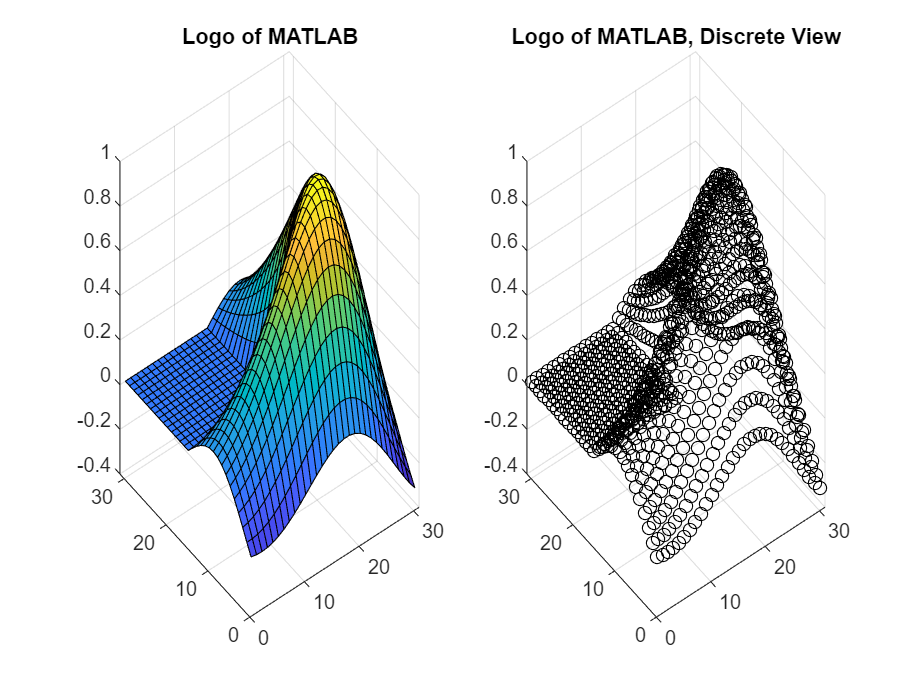

GridNumber=numel(x);
figure
subplot(1,2,1)
surf(X,Y,reshape(label,GridNumber,GridNumber))
title('Logo of MATLAB')
subplot(1,2,2)
scatter3(data(1,:),data(2,:),label,'black')
title('Logo of MATLAB, Discrete View')

Our goal is to find a surface that represents the input-output relation between the data and label.

### 3. Specify The Structure & Type of Neural Networks

The package support two types of Neural Nets for function approximation & data fitting,

the first is Multilayer Perceptron (MLP) , the second is Residual Neural Networks (ResNet).

**ResNet can make training neural networks easier, the effectiveness is particularly **

**evident when the network is very deep.**

To specify the type of network, use the command: `NN.NetworkType='ANN'` or `'ResNet'`, 

close all
NN.NetworkType='ANN'; % MLP

The logo of MATLAB is a function with 2 input 1 output, i.e.$\;f\left(\mathit{\mathbf{x}}\right):R^2 \to R$ 

Define the network structure using following command:

InputDimension=2; OutputDimension=1;
LayerStruct=[InputDimension,8,8,8,OutputDimension];

**The number between Input & OutputDimension are the size of hidden layers,**

**larger hidden layer sizes and deeper networks lead to better approximation of complex functions**.

To specify the cost function to minimize using `NN.Cost`, you can choose between 

three options provided by the package, which are  Sum of Square Error (SSE), Mean Square Error (MSE, suitable for

data fitting without noise and function approximation) and Mean Absolute Error (MAE, suitable for noisy data fitting)


$${\;\mathit{\mathbf{E}}\left(\mathit{\mathbf{W}},\mathit{\mathbf{b}}\right)=\mathit{\mathbf{Y}}-\textrm{NN}\left(\mathit{\mathbf{W}},\mathit{\mathbf{b}},\mathit{\mathbf{D}}\right),\;J}_{\textrm{MSE}} \left(\mathit{\mathbf{W}},\mathit{\mathbf{b}}\right)\equiv \frac{\left\|\mathit{\mathbf{E}}\left(\mathit{\mathbf{W}},\mathit{\mathbf{b}}\right){\left\|\right.}^2 \right.}{n_D },J_{\textrm{MAE}} \left(\mathit{\mathbf{W}},\mathit{\mathbf{b}}\right)\equiv \frac{\left|\mathit{\mathbf{E}}\left(\mathit{\mathbf{W}},\mathit{\mathbf{b}}\right)\right|}{n_D }$$


NN.Cost='SSE'; 

You can specify the nonlinear activation function for your neural network using `NN.ActivationFunction`.

Currently, there are four built-in activation functions available, which are:

1. Gaussian 

2. Sigmoid

3. tanh

4. ReLU

5. Wavelet

The recommended activation function for function approximation is `'Gaussian'`.

NN.ActivationFunction='Gaussian';

You can also use a function handle to define custom activation function.

When using function handles to define custom activation, remember to provide the derivatives as well.

% NN.ActivationFunction=@(x) exp(-x.^2);
% NN.activeDerivate=@(x) -2*x.*exp(-x.^2); % derivative of gaussian

The activation should be smooth for function approximation problems, so those commonly used activation for 

classification problems like 'ReLU' are not recommand.

For ill-behaved datasetsill-behaved datasets metioned in section 1, preprocessing of the data before optimization is necessary. 

Alternatively, you can use the built-in function to automatically perform preprocessing (normailzation).

% NN.InputAutoScaling='on';
% NN.LabelAutoScaling='on';

Detailed explanation can be found in `"TipsForTrainingNeuralNet.mlx"`.

Finally, use the command 'Initialization' to Initialize the weights & biases of NN.

NN=Initialization(LayerStruct,NN);

### 4. Solve Least Squares Problem By Numerical Optimization

Our goal is to find optimal parameters ${\mathit{\mathbf{W}}}^* ,{\mathit{\mathbf{b}}}^*$ such that minimize the cost function $J\left(\mathit{\mathbf{W}},\mathit{\mathbf{b}}\right)$ , i.e.


$${\mathit{\mathbf{W}}}^* ,{\mathit{\mathbf{b}}}^* \;=\;\textrm{argmin}\;\;\left\|\mathit{\mathbf{Y}}-\textrm{NN}\left(\mathit{\mathbf{W}},\mathit{\mathbf{b}},\mathit{\mathbf{D}}\right){\left\|\right.}^2 \right.$$


The standard workflow can be separated into two stages. First use stochastic gradient descent-based methods (SGD)

 to avoid getting stuck in local minima. For SGD-based algorithms, the following information is required:

#### 4.1 Stochastic Gradient Descent Based Method

option.Solver='ADAM';
option.BatchSize=100;
option.MaxIteration=20;
option.s0=2e-3; % Step Size
NN=OptimizationSolver(data,label,NN,option);

Iteration : 1 , Cost :      87.40805614 
Iteration : 2 , Cost :      84.50008922 
Iteration : 3 , Cost :      82.17817358 
Iteration : 4 , Cost :      78.75882006 
Iteration : 5 , Cost :      74.65420815 
Iteration : 6 , Cost :      69.68327716 
Iteration : 7 , Cost :      63.72717552 
Iteration : 8 , Cost :      57.21862755 
Iteration : 9 , Cost :      51.32185497 
Iteration : 10 , Cost :      45.40799044 
Iteration : 11 , Cost :      40.79798658 
Iteration : 12 , Cost :      37.04029401 
Iteration : 13 , Cost :      34.53779423 
Iteration : 14 , Cost :      32.19926879 
Iteration : 15 , Cost :      30.81699083 
Iteration : 16 , Cost :      29.29917356 
Iteration : 17 , Cost :      28.43830068 
Iteration : 18 , Cost :      27.16526463 
Iteration : 19 , Cost :      26.89070376 
Iteration : 20 , Cost :      25.74577724 
------------------------------------------------------
Max Iteration : 20 , Cost :      25.74577724 
Optimization Time :   0.1
Mean Absolute Error :   0.1191
-----------

#### 4.2 Quasi-Newton Method

Quasi-Newton methods are much superior to SGD-Based methods (superlinear v.s. linear convergence rate) 

in small-to-medium-size least-square problems, using Quasi-Newton methods can significantly accelerate the 

optimization.

The following information are required when using Quasi-Newton's methods.

If the infinity norm of the gradient is less than terminate condition, the optimization process will be stop.

option.Solver='BFGS';
option.MaxIteration=550;
option.TerminateCondition=1e-6; % optional
NN=OptimizationSolver(data,label,NN,option);

Iteration : 27 , Cost :      18.83059694 
Iteration : 54 , Cost :       2.10215553 
Iteration : 81 , Cost :       1.40761280 
Iteration : 108 , Cost :       0.53413250 
Iteration : 135 , Cost :       0.24097846 
Iteration : 162 , Cost :       0.13515144 
Iteration : 189 , Cost :       0.09644568 
Iteration : 216 , Cost :       0.07452736 
Iteration : 243 , Cost :       0.05928728 
Iteration : 270 , Cost :       0.04650270 
Iteration : 297 , Cost :       0.03823851 
Iteration : 324 , Cost :       0.03140106 
Iteration : 351 , Cost :       0.02471616 
Iteration : 378 , Cost :       0.02011590 
Iteration : 405 , Cost :       0.01667153 
Iteration : 432 , Cost :       0.01426195 
Iteration : 459 , Cost :       0.01294289 
Iteration : 486 , Cost :       0.01183187 
Iteration : 513 , Cost :       0.01068265 
Iteration : 540 , Cost :       0.00946014 
------------------------------------------------------
Max Iteration : 550 , Cost :       0.00874130 
Optimization Time :   2.1
Mean Absolute E

### 5. Quatify & Visualize Fitting Performance

Use NN.Evaluate to predict & analyzing fitting results. 

you can quatify the fitting performance  by the error matrix : $\mathit{\mathbf{E}}=\mathit{\mathbf{Y}}-\textrm{NN}\left(\mathit{\mathbf{D}}\right)$

or use the function `"FittingReport"` to quantify and visualize the performance rapidly.

--- FittingReport ---
Samples: 961, Outputs: 1
Vector storage: all
  y      R^2          MAE          RMSE         Bias         MSE         
  y1     0.999899     0.00211906   0.00301597   8.79986e-06  9.09605e-06 
---------------------



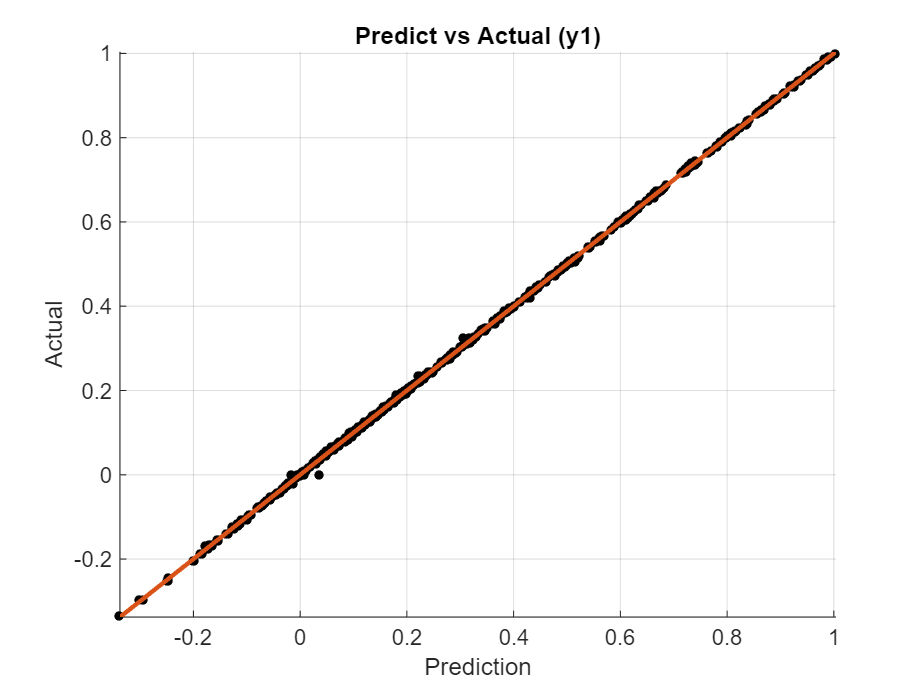

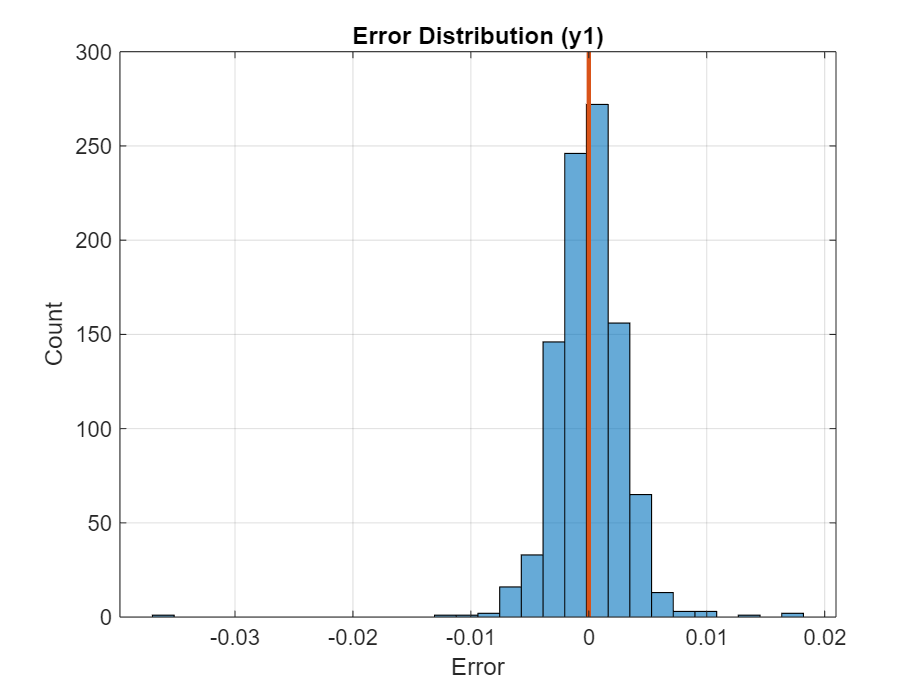

Prediction=NN.Evaluate(data);
Report=FittingReport(data,label,NN);

Visualize the optimized neural network

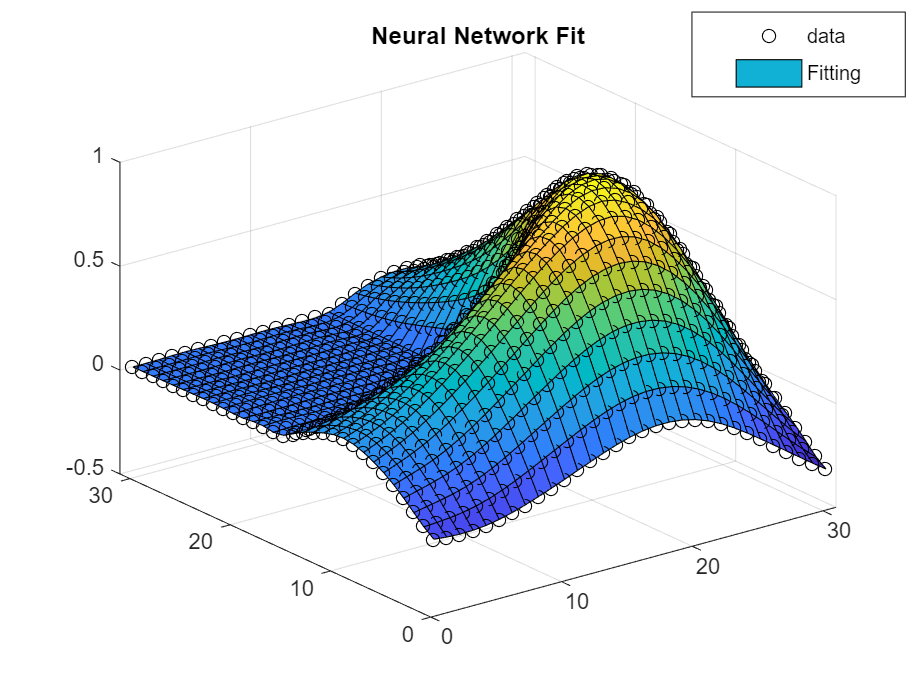

figure
scatter3(data(1,:),data(2,:),label(1,:),'black') 
hold on
[X,Y]=meshgrid(x,y);
n1=numel(x); n2=numel(y);
surf(X,Y,reshape(Prediction(1,:),n1,n2))
title('Neural Network Fit')
legend('data','Fitting')
legend("Position", [0.74834,0.86095,0.23184,0.12127])

FirstOrderOptimality=NN.FirstOrderOptimality

FirstOrderOptimality = 1.7407

The first order optimality may indicate the fitting potential of neural net, if the first order optimality is still large after optimization, you may consider using the BFGS method for further optimization of the neural network.

option.Solver='BFGS';
option.MaxIteration=100;
NN=OptimizationSolver(data,label,NN,option);

Iteration : 5 , Cost :       0.00872874 
Iteration : 10 , Cost :       0.00872006 
Iteration : 15 , Cost :       0.00871465 
Iteration : 20 , Cost :       0.00870762 
Iteration : 25 , Cost :       0.00870146 
Iteration : 30 , Cost :       0.00869230 
Iteration : 35 , Cost :       0.00868329 
Iteration : 40 , Cost :       0.00867524 
Iteration : 45 , Cost :       0.00866025 
Iteration : 50 , Cost :       0.00864580 
Iteration : 55 , Cost :       0.00863045 
Iteration : 60 , Cost :       0.00861246 
Iteration : 65 , Cost :       0.00859496 
Iteration : 70 , Cost :       0.00856548 
Iteration : 75 , Cost :       0.00853398 
Iteration : 80 , Cost :       0.00849375 
Iteration : 85 , Cost :       0.00841814 
Iteration : 90 , Cost :       0.00829473 
Iteration : 95 , Cost :       0.00817427 
Iteration : 100 , Cost :       0.00800051 
------------------------------------------------------
Max Iteration : 100 , Cost :       0.00800051 
Optimization Time :   0.5
Mean Absolute Error :   0.0019
-

clear option; % clear solver setting for next section.

### 6. Train Neural Network Quickly with a Few Lines of Code

If the user did not provide solver options, the pack will perform the two-stage optimization automatically, 

that is, using 'ADAM' to find better initial parameters for the Quasi-Newton method, than applying 'BFGS'

solver to accelerate convergence.

% Structure Set Up
InputDimension=2; OutputDimension=1;
LayerStruct=[InputDimension,7,7,8,7,7,OutputDimension];
NN=Initialization(LayerStruct);
% Solver Set Up
option.MaxIteration=600;
NN=OptimizationSolver(data,label,NN,option);

Iteration : 7 , Cost :       0.17647171 
Iteration : 14 , Cost :       0.10864026 
Iteration : 21 , Cost :       0.09271308 
Iteration : 28 , Cost :       0.08575096 
Iteration : 35 , Cost :       0.08049857 
Iteration : 42 , Cost :       0.07396149 
Iteration : 49 , Cost :       0.07216257 
Iteration : 56 , Cost :       0.06921750 
Iteration : 63 , Cost :       0.06710528 
Iteration : 70 , Cost :       0.06762928 
Iteration : 77 , Cost :       0.06524048 
Iteration : 84 , Cost :       0.06222377 
Iteration : 91 , Cost :       0.06393177 
Iteration : 98 , Cost :       0.06045880 
Iteration : 105 , Cost :       0.05409182 
Iteration : 112 , Cost :       0.05603869 
Iteration : 119 , Cost :       0.03094352 
Iteration : 126 , Cost :       0.02638018 
Iteration : 133 , Cost :       0.02015182 
Iteration : 140 , Cost :       0.01562922 
Iteration : 147 , Cost :       0.01431934 
------------------------------------------------------
First Stage Optimization Finished in  150  Iteration.
---

--- FittingReport ---
Samples: 961, Outputs: 1
Vector storage: all
  y      R^2          MAE          RMSE         Bias         MSE         
  y1     0.99899      0.00523211   0.00952625   0.000143939  9.07494e-05 
---------------------



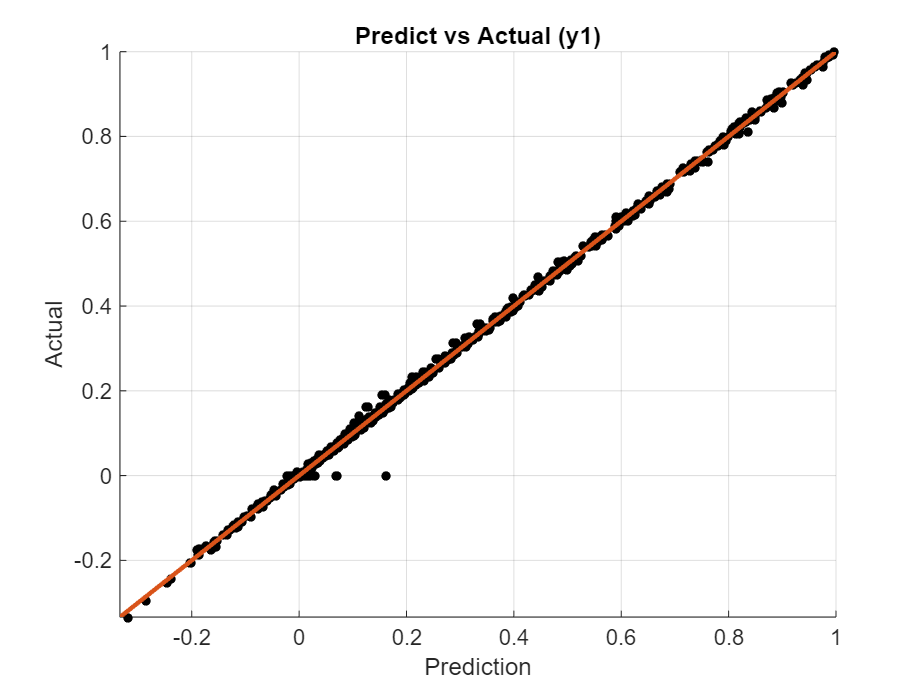

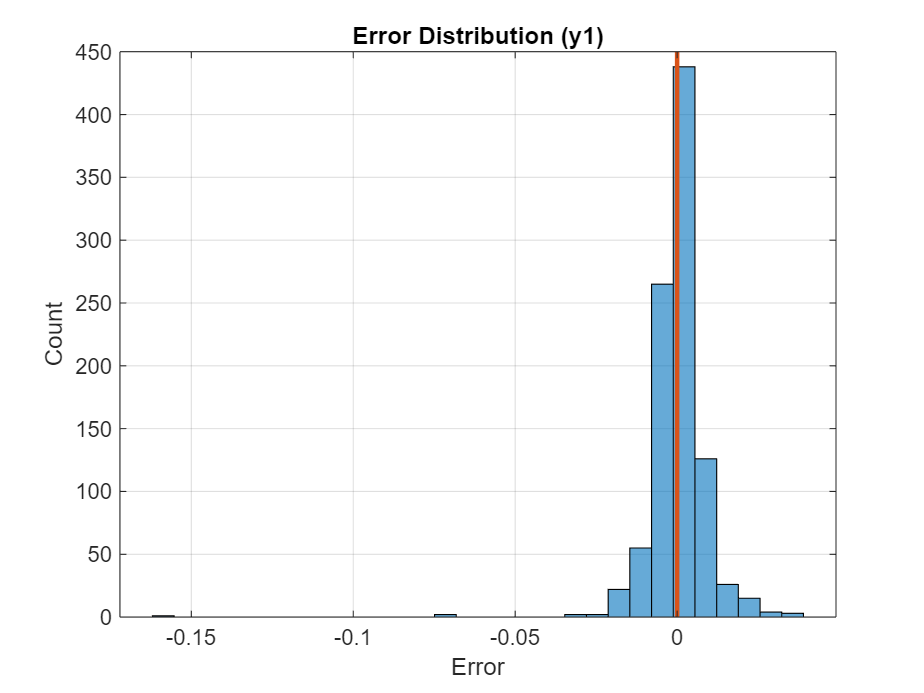

% Validate Results
Report=FittingReport(data,label,NN);